# Calibrated parameters

#### Accelerometer

b_acc_prop = [0.0041 0.0004 -0.0019];
M_acc_prop = [0.9994   -0.0001   -0.0002;...
             -0.0001    0.9998   -0.0001;...
             -0.0002   -0.0001    0.9983];
b_acc_6_turns = [0.0183 0.0289  -0.0768];
M_acc_6_turns = eye(3)-[0.0002  0.0062   -0.0036;...    
                 0.0087  0.0002    0.0048;...    
                -0.0011  0.0013    0.0014];

#### Gyroscope

b_gyro_prop = [0.0029 -1.6837e-05 0.0012];
b_gyro_6_turns = [0.003 -3.8e-4  0.0012];
S_gyro_6_turns = [0.7219 0.7289 0.2476];


# Load scenario data

dt = 1/100; % [Hz]
g = 9.79;
tile_length = 0.315; %[m]
num_tiles = 13;
load('rec12_x_axis.mat')

# Calculate position with both calibration parameters

integrate on full recording

acc_prop = M_acc_prop*([Acceleration.X Acceleration.Y Acceleration.Z] - b_acc_prop)'-[0; 0; g];
v_prop = cumsum(acc_prop,2)*dt;
p_prop = cumsum(v_prop,2)*dt;
acc_6_turns = M_acc_6_turns*([Acceleration.X Acceleration.Y Acceleration.Z] - b_acc_6_turns)'-[0; 0; g];
v_6_turns = cumsum(acc_6_turns,2)*dt;
p_6_turns = cumsum(v_6_turns,2)*dt;

# Plot results

close all
time = datevec(Acceleration.Timestamp);
time = time(:,5)*60 + time(:,6)-time(1,5)*60 - time(1,6);

#### Acceleration plots

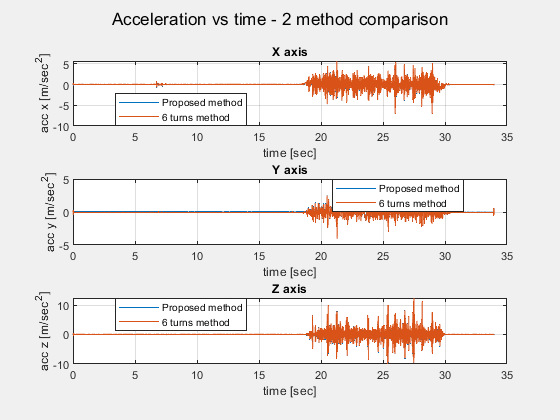

figure
set(gcf,'Visible','on')
ax1 = subplot(3,1,1); % acc x axis
plot(time,acc_prop(1,:),'DisplayName','Proposed method')
hold on; grid on
plot(time,acc_6_turns(1,:),'DisplayName','6 turns method')
xlabel('time [sec]')
ylabel('acc x [m/sec^2]')
title('X axis')
legend('Location','best')
ax2 = subplot(3,1,2); % acc y axis
plot(time,acc_prop(2,:),'DisplayName','Proposed method')
hold on; grid on
plot(time,acc_6_turns(2,:),'DisplayName','6 turns method')
xlabel('time [sec]')
ylabel('acc y [m/sec^2]')
title('Y axis')
legend('Location','best')
ax3 = subplot(3,1,3); % acc z axis
plot(time,acc_prop(3,:),'DisplayName','Proposed method')
hold on; grid on
plot(time,acc_6_turns(3,:),'DisplayName','6 turns method')
xlabel('time [sec]')
ylabel('acc z [m/sec^2]')
title('Z axis')
sgtitle('Acceleration vs time - 2 method comparison')
legend('Location','best')
linkaxes([ax1 ax2 ax3],'x')

#### Linear velocity plots

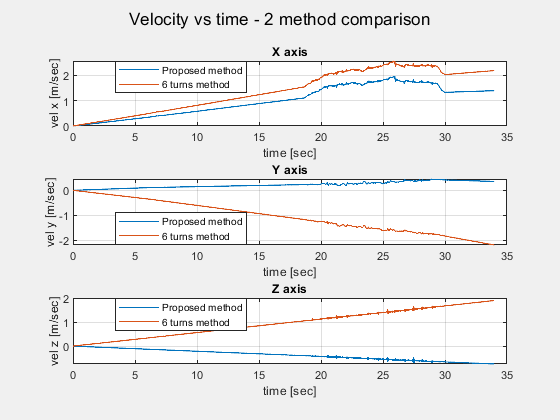

figure
set(gcf,'Visible','on')
ax1 = subplot(3,1,1); % vel x axis
plot(time,v_prop(1,:),'DisplayName','Proposed method')
hold on; grid on
plot(time,v_6_turns(1,:),'DisplayName','6 turns method')
xlabel('time [sec]')
ylabel('vel x [m/sec]')
title('X axis')
legend('Location','best')
ax2 = subplot(3,1,2); % acc y axis
plot(time,v_prop(2,:),'DisplayName','Proposed method')
hold on; grid on
plot(time,v_6_turns(2,:),'DisplayName','6 turns method')
xlabel('time [sec]')
ylabel('vel y [m/sec]')
title('Y axis')
legend('Location','best')
ax3 = subplot(3,1,3); % acc z axis
plot(time,v_prop(3,:),'DisplayName','Proposed method')
hold on; grid on
plot(time,v_6_turns(3,:),'DisplayName','6 turns method')
xlabel('time [sec]')
ylabel('vel z [m/sec]')
title('Z axis')
sgtitle('Velocity vs time - 2 method comparison')
legend('Location','best')
linkaxes([ax1 ax2 ax3],'x')

#### Position plots

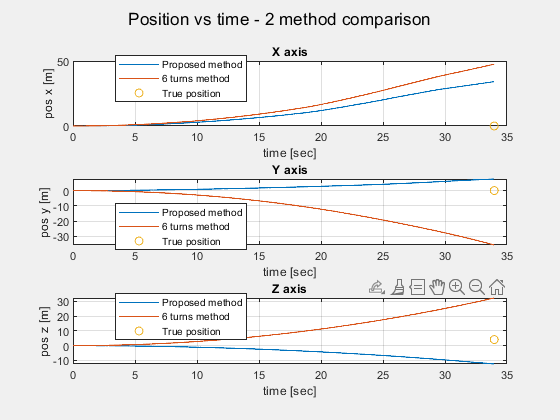

figure
set(gcf,'Visible','on')
ax1 = subplot(3,1,1); % pos x axis
plot(time,p_prop(1,:),'DisplayName','Proposed method')
hold on; grid on
plot(time,p_6_turns(1,:),'DisplayName','6 turns method')
plot(time(end),0,'o','DisplayName','True position')
% plot(time(end),tile_length*num_tiles,'o','DisplayName','True position')
xlabel('time [sec]')
ylabel('pos x [m]')
title('X axis')
legend('Location','best')
ax2 = subplot(3,1,2); % pos y axis
plot(time,p_prop(2,:),'DisplayName','Proposed method')
hold on; grid on
plot(time,p_6_turns(2,:),'DisplayName','6 turns method')
plot(time(end),0,'o','DisplayName','True position')
% plot(time(end),tile_length*num_tiles,'o','DisplayName','True position')
xlabel('time [sec]')
ylabel('pos y [m]')
title('Y axis')
legend('Location','best')
ax3 = subplot(3,1,3); % pos z axis
plot(time,p_prop(3,:),'DisplayName','Proposed method')
hold on; grid on
plot(time,p_6_turns(3,:),'DisplayName','6 turns method')
% plot(time(end),0,'o','DisplayName','True position')
plot(time(end),tile_length*num_tiles,'o','DisplayName','True position')
xlabel('time [sec]')
ylabel('pos z [m]')
title('Z axis')
sgtitle('Position vs time - 2 method comparison')
legend('Location','best')

linkaxes([ax1 ax2 ax3],'x')

# Calculate position with both calibration parameters

integrate on dynamic section in recording

acc_prop = M_acc_prop*([Acceleration.X Acceleration.Y Acceleration.Z] - b_acc_prop)'-[0; 0; g];

#### Find dynamic section

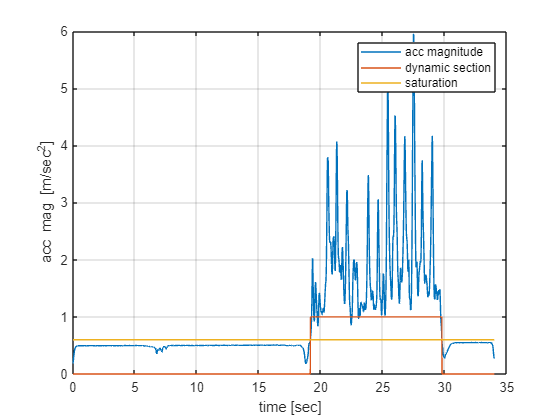

% Compute accelerometer magnitude
acc_mag = sqrt(acc_prop(1,:).*acc_prop(1,:) + acc_prop(2,:).*acc_prop(2,:)+ acc_prop(3,:).*acc_prop(3,:));

% HP filter accelerometer data
filtCutOff = 0.001;
[b, a] = butter(1, (2*filtCutOff)/(1/dt), 'high');
acc_magFilt = filtfilt(b, a, acc_mag);

% Compute absolute value
acc_magFilt = abs(acc_magFilt);

% LP filter accelerometer data
filtCutOff = 3;
[b, a] = butter(1, (2*filtCutOff)/(1/dt), 'low');
acc_magFilt = filtfilt(b, a, acc_magFilt);

% Threshold detection
sat =0.6;
dynamic = acc_magFilt > sat;
figure;
time_temp = datevec(Acceleration.Timestamp);
time_temp = time_temp(:,5)*60 + time_temp(:,6)-time_temp(1,5)*60 - time_temp(1,6);
plot(time_temp,acc_magFilt,'DisplayName','acc magnitude')
hold on; grid on
plot(time_temp,dynamic,'DisplayName','dynamic section')
plot(time_temp,sat*ones(1,length(time_temp)),'DisplayName','saturation')
xlabel('time [sec]')
ylabel('acc mag [m/sec^2]')
legend

#### Calculate position using integration only in dynamic section

v_prop = cumsum(acc_prop(:,dynamic),2)*dt;
p_prop = cumsum(v_prop,2)*dt;
acc_6_turns = M_acc_6_turns*([Acceleration.X Acceleration.Y Acceleration.Z] - b_acc_6_turns)'-[0; 0; g];
v_6_turns = cumsum(acc_6_turns(:,dynamic),2)*dt;
p_6_turns = cumsum(v_6_turns,2)*dt;

# Plot results

% close all
time = datevec(Acceleration.Timestamp(dynamic));
time = time(:,5)*60 + time(:,6)-time(1,5)*60 - time(1,6);

#### Linear velocity plots

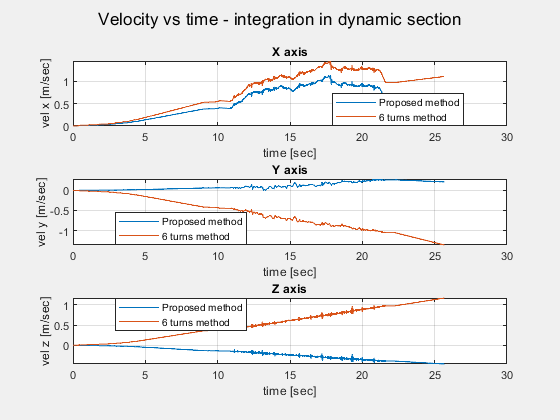

figure
set(gcf,'Visible','on')
ax1 = subplot(3,1,1); % vel x axis
plot(time,v_prop(1,:),'DisplayName','Proposed method')
hold on; grid on
plot(time,v_6_turns(1,:),'DisplayName','6 turns method')
xlabel('time [sec]')
ylabel('vel x [m/sec]')
title('X axis')
legend('Location','best')
ax2 = subplot(3,1,2); % acc y axis
plot(time,v_prop(2,:),'DisplayName','Proposed method')
hold on; grid on
plot(time,v_6_turns(2,:),'DisplayName','6 turns method')
xlabel('time [sec]')
ylabel('vel y [m/sec]')
title('Y axis')
legend('Location','best')
ax3 = subplot(3,1,3); % acc z axis
plot(time,v_prop(3,:),'DisplayName','Proposed method')
hold on; grid on
plot(time,v_6_turns(3,:),'DisplayName','6 turns method')
xlabel('time [sec]')
ylabel('vel z [m/sec]')
title('Z axis')
sgtitle('Velocity vs time - integration in dynamic section')
legend('Location','best')

linkaxes([ax1 ax2 ax3],'x')

#### Position plots

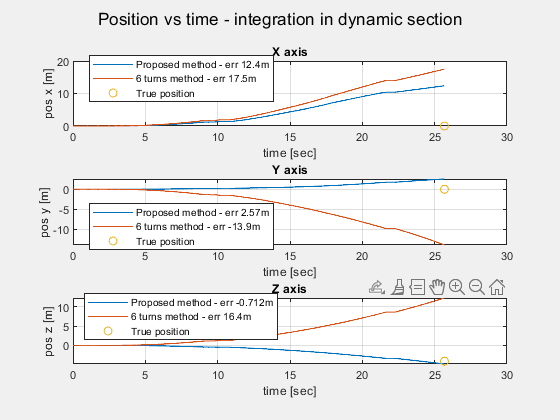

figure
set(gcf,'Visible','on')
ax1 = subplot(3,1,1); % pos x axis
x_final = 0; % tile_length*num_tiles
plot(time,p_prop(1,:),'DisplayName',['Proposed method - err ',num2str(p_prop(1,end)-x_final,3),'m'])
hold on; grid on
plot(time,p_6_turns(1,:),'DisplayName',['6 turns method - err ',num2str(p_6_turns(1,end)-x_final,3),'m'])
plot(time(end),x_final,'o','DisplayName','True position')
xlabel('time [sec]')
ylabel('pos x [m]')
title('X axis')
legend('Location','best')
ax2 = subplot(3,1,2); % pos y axis
y_final = 0;
plot(time,p_prop(2,:),'DisplayName',['Proposed method - err ',num2str(p_prop(2,end)-y_final,3),'m'])
hold on; grid on
plot(time,p_6_turns(2,:),'DisplayName',['6 turns method - err ',num2str(p_6_turns(2,end)-y_final,3),'m'])
plot(time(end),y_final,'o','DisplayName','True position')
xlabel('time [sec]')
ylabel('pos y [m]')
title('Y axis')
legend('Location','best')
ax3 = subplot(3,1,3); % pos z axis
z_final = -tile_length*num_tiles;
plot(time,p_prop(3,:),'DisplayName',['Proposed method - err ',num2str(p_prop(3,end)-z_final,3),'m'])
hold on; grid on
plot(time,p_6_turns(3,:),'DisplayName',['6 turns method - err ',num2str(p_6_turns(3,end)-z_final,3),'m'])
plot(time(end),z_final,'o','DisplayName','True position')
xlabel('time [sec]')
ylabel('pos z [m]')
title('Z axis')
sgtitle('Position vs time - integration in dynamic section')
legend('Location','best')

linkaxes([ax1 ax2 ax3],'x')